The script is modified from the one given by Prof. Gabe, which computes the *concentration for given reaction * and we have following denotion definition:

- substrate -> S 

- enzyme -> E

- sub-enzyme complex -> SE

- product -> P 

- Inhibitor ->  I

- Inhib-Enz complex -> IE

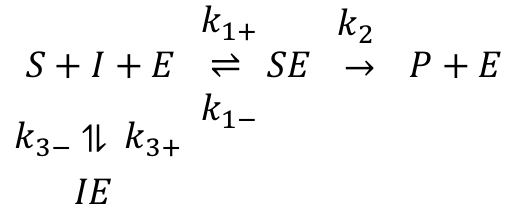

which can be represented mathmatically as a set of ordinary differential equations:


$$\begin{array}{l}
\frac{\mathrm{d}\left\lbrack \mathrm{S}\right\rbrack }{\text{dt}}=-k_{1+} \left\lbrack \mathrm{S}\right\rbrack \left\lbrack \mathrm{E}\right\rbrack +k_{1-} \left\lbrack \text{SE}\right\rbrack \\
\frac{\mathrm{d}\left\lbrack E\right\rbrack }{\text{dt}}={-k}_{1+} \left\lbrack \mathrm{S}\right\rbrack \left\lbrack \mathrm{E}\right\rbrack +\left(k_{1-} +k_2 \right)\left\lbrack \text{SE}\right\rbrack +k_{3-} \left\lbrack \mathrm{IE}\right\rbrack -k_{3+} \left\lbrack I\right\rbrack \left\lbrack E\right\rbrack \\
\frac{\mathrm{d}\left\lbrack \text{SE}\right\rbrack }{\text{dt}}=k_{1+} \left\lbrack \mathrm{S}\right\rbrack \left\lbrack \mathrm{E}\right\rbrack -\left(k_{1-} +k_2 \right)\left\lbrack \text{SE}\right\rbrack \\
\frac{\mathrm{d}\left\lbrack \mathrm{P}\right\rbrack }{\text{dt}}=k_2 \left\lbrack \text{SE}\right\rbrack \\
\frac{\mathrm{d}\left\lbrack I\right\rbrack }{\text{dt}}=k_{3-} \left\lbrack \mathrm{IE}\right\rbrack -k_{3+} \left\lbrack I\right\rbrack \left\lbrack E\right\rbrack \\
\frac{\mathrm{d}\left\lbrack \mathit{IE}\right\rbrack }{\text{dt}}={-k}_{3-} \left\lbrack I\text{E}\right\rbrack +k_{3+} \left\lbrack I\right\rbrack \left\lbrack E\right\rbrack 
\end{array}$$


Note that: 

- E_total = E_free + E_(IE) + E_(SE)  |    S_total = S_free + S_(SE) 

- For certain chemical equations, such as S+I+E <-> SE (alongside I + E <-> IE), I actually does NOT involve in the Sub-Enz complex reaction, that is why we do NOT take [I] into account when decribing the S+I+E <-> SE chemical equation. 

- Below part we just configure scripts with required parameters, which is available via canvas.umich.edu (BIOMEDE 519)

% concentration init
S_0 = 1;                                     % Starting concen of Substrate (mM)                                
E_0 = 0.15;                                  % Starting concen of Enzyme (mM)                              % Starting concen of SE complex (mM)
P_0 = 0;                                     % Starting concen of Product (mM)
I_0 = 0.20;
SE_0 = 0;
IE_0 = 0;

% reaction Rate config p->plus(+) m->minus(-) unit: 1/(mM*s)
k_1p = 0.50;                                 % Reaction 1 forward rate constant ()
k_1m = 0.10;                                 % Reaction 1 reverse rate constant (1/s)
k_2  = 0.10;                                 % Reaction 2 rate constant (1/s)
k_3p = 0.15;                                 
k_3m = 0.05;

% simulation time config
t_start = 0;                                 % Simulation start time (s)
t_end = 500;                                 % Simulation end time (s)

Now we can solve the set of ODEs expressed in the function dXdt over the entire time course using the prepackaged ODE solver ode15s. Syntax is [t_Out,X_Out] = ode15s(ODEfun,tspan,X_IC)


[t_Out,X_Out] = ode15s(@(t,X) dXdt(t,X,k_1p,k_1m,k_2,k_3p,k_3m,E_0, I_0, IE_0, SE_0), ...
                        [t_start t_end], ...
                        [S_0,E_0,P_0,I_0]);

未定义函数或变量 'I'。

出错 test>dXdt (line 58)
    IE = I_0 + IE_0 -I;

出错 test>@(t,X)dXdt(t,X,k_1p,k_1m,k_2,k_3p,k_3m,E_0,I_0,IE_0,SE_0)

出错 odearguments (line 90)
f0 = feval(ode,t0,y0,args{:});   % ODE15I sets args{1} to yp0.

出错 

Take the solution vector, X_Out, set it to A, calculate B and plot

S_Out = X_Out(:,1);                        % Set [S] with ode15s solution
E_Out = X_Out(:,2);                        % Set [E] with ode15s solution
P_Out = X_Out(:,3);                        % Set [P] with ode15s solution
I_Out = X_Out(:,4);
IE_Out = I_0 + IE_0 - I_Out;
SE_Out = E_0 + IE_0 + SE_0 - E_Out - IE_Out;
% ES_Out = E_0 - X_Out(:,2);                 % Calculate [ES]

figure(1)                                  % Plotting
plot(t_Out,S_Out,'LineWidth',2)  
hold on
 plot(t_Out,E_Out,'LineWidth',2)
 plot(t_Out,SE_Out,'LineWidth',2)
 plot(t_Out,P_Out,'Linewidth',2)
 plot(t_Out,I_Out,'Linewidth',2)
 plot(t_Out,IE_Out, 'LineWidth',2)
ylim([0 1.0])
xlabel('time (s)','FontSize',16,'FontWeight','bold')
ylabel('Concentration (mM)','FontSize',16,'FontWeight','bold')
leghndl = legend('[S]','[E]','[SE]','[P]','[I]','[IE]');
set(leghndl,'FontSize',14)
hold off

HERE is the exact function that estimates the change in each of the concentrations at each time step:


$$\begin{array}{l}
\frac{\mathrm{d}\left\lbrack \mathrm{S}\right\rbrack }{\text{dt}}=-k_{1+} \left\lbrack \mathrm{S}\right\rbrack \left\lbrack \mathrm{E}\right\rbrack +k_{1-} \left\lbrack \text{SE}\right\rbrack \\
\frac{\mathrm{d}\left\lbrack E\right\rbrack }{\text{dt}}={-k}_{1+} \left\lbrack \mathrm{S}\right\rbrack \left\lbrack \mathrm{E}\right\rbrack +\left(k_{1-} +k_2 \right)\left\lbrack \text{SE}\right\rbrack +k_{3-} \left\lbrack \text{IE}\right\rbrack -k_{3+} \left\lbrack I\right\rbrack \left\lbrack E\right\rbrack \\
\frac{\mathrm{d}\left\lbrack \mathrm{P}\right\rbrack }{\text{dt}}=k_2 \left\lbrack \text{SE}\right\rbrack \\
\frac{\mathrm{d}\left\lbrack I\right\rbrack }{\text{dt}}=k_{3-} \left\lbrack \text{IE}\right\rbrack -k_{3+} \left\lbrack I\right\rbrack \left\lbrack E\right\rbrack \\
\frac{\mathrm{d}\left\lbrack \text{SE}\right\rbrack }{\text{dt}}=k_{1+} \left\lbrack \mathrm{S}\right\rbrack \left\lbrack \mathrm{E}\right\rbrack -\left(k_{1-} +k_2 \right)\left\lbrack \text{SE}\right\rbrack \\
\\
\frac{\mathrm{d}\left\lbrack \mathit{\text{IE}}\right\rbrack }{\text{dt}}={-k}_{3-} \left\lbrack I\mathrm{E}\right\rbrack +k_{3+} \left\lbrack I\right\rbrack \left\lbrack E\right\rbrack 
\end{array}$$

$$\begin{array}{l}
\\

\end{array}$$


 whenever ode15s calls it. 

function RoC = dXdt(~, X, k_1p, k_1m, k_2, k_3p, k_3m, E_0, I_0, IE_0, SE_0)
    % notice: modified already, for sake of dealing with newly added variables. 
    % also available via canvas (BIOMEDE 519)
    % NOTE:
        % X_Out = [ S | E | P | I | SE
        % [E] + [SE] + [IE] = E_0 + SE_0 + IE_0   %% conservation of E(Enz only exist in form of E/SE/IE)
        % [IE] + [I] = I_0 + IE_0  %% conservation of I(Inhib only exitst in form of I/IE)
    
    S = X(1);                                             % Setting current S
    E = X(2);                                             % Setting current E
    P = X(3);
    I = X(4);
    IE = I_0 + IE_0 -I;
    SE = E_0 + SE_0 + IE_0 - E - IE;
    
    dSdt = (-k_1p * S * E) + (k_1m * SE);          % Calculation of dS/dt
    dEdt = (-k_1p * S * E) + ((k_1m + k_2) * SE) + k_3m * IE - k_3p * I * E;  % Calculation of dE/dt
    dPdt = k_2 * SE;
    dIdt = k_3m * IE - k_3p * I * E;
    
    RoC(1) = dSdt;                                        % Set to RoC vector
    RoC(2) = dEdt;
    RoC(3) = dPdt;
    RoC(4) = dIdt;
    RoC = RoC';                                           % Put into column vector
    
    
end
